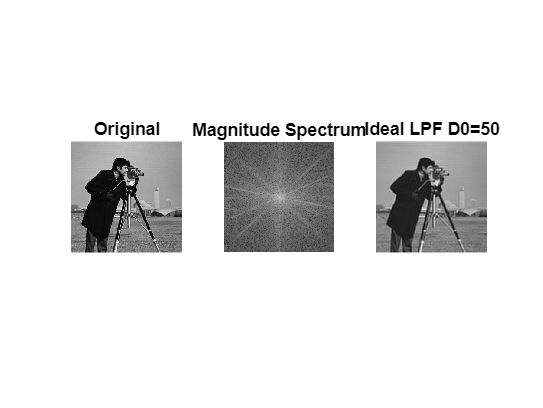

img = imread('cameraman.tif');
if ndims(img)==3
    img = rgb2gray(img);
end
img = double(img);
[M,N] = size(img);
F = fft2(img);
F_shifted = fftshift(F);
magSpec = log(abs(F_shifted)+1);
DO = 50;
h = zeros(M,N);
for u=1:M
    for v=1:N
        D = sqrt((u - M/2)^2 + (v - N/2)^2);
        if D <= DO
            h(u,v) = 1;
        end
    end
end
G = h .* F_shifted;
filtered_img = real(ifft2(ifftshift(G)));
figure;
subplot(1,3,1); imshow(uint8(img)); title('Original');
subplot(1,3,2); imshow(magSpec, []); title('Magnitude Spectrum');
subplot(1,3,3); imshow(filtered_img, []); title('Ideal LPF D0=50');

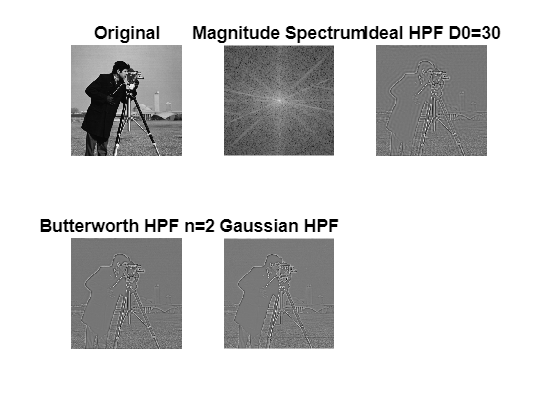

DO = 30;
h_high = zeros(M,N);
for u=1:M
    for v=1:N
        D = sqrt((u - M/2)^2 + (v - N/2)^2);
        if D > DO
            h_high(u,v) = 1;
        end
    end
end
G_high = h_high .* F_shifted;
filtered_high = real(ifft2(ifftshift(G_high)));
n = 2;
H_b = zeros(M,N);
for u=1:M
    for v=1:N
        D = sqrt((u - M/2)^2 + (v - N/2)^2);
        H_b(u,v) = 1/(1 + (D/DO)^(2*n));
    end
end
H_bh = 1 - H_b;
G_bh = H_bh .* F_shifted;
img_bh = real(ifft2(ifftshift(G_bh)));
H_g = zeros(M,N);
for u=1:M
    for v=1:N
        D = sqrt((u - M/2)^2 + (v - N/2)^2);
        H_g(u,v) = exp(-(D^2)/(2*(DO^2)));
    end
end
H_gh = 1 - H_g;
G_gh = H_gh .* F_shifted;
img_gh = real(ifft2(ifftshift(G_gh)));
figure;
subplot(2,3,1); imshow(uint8(img)); title('Original');
subplot(2,3,2); imshow(magSpec, []); title('Magnitude Spectrum');
subplot(2,3,3); imshow(filtered_high, []); title('Ideal HPF D0=30');
subplot(2,3,4); imshow(img_bh, []); title('Butterworth HPF n=2');
subplot(2,3,5); imshow(img_gh, []); title('Gaussian HPF');